x1=[2 3 4];
x2=[3 4 5 6];
x3=conv(x1,x2)

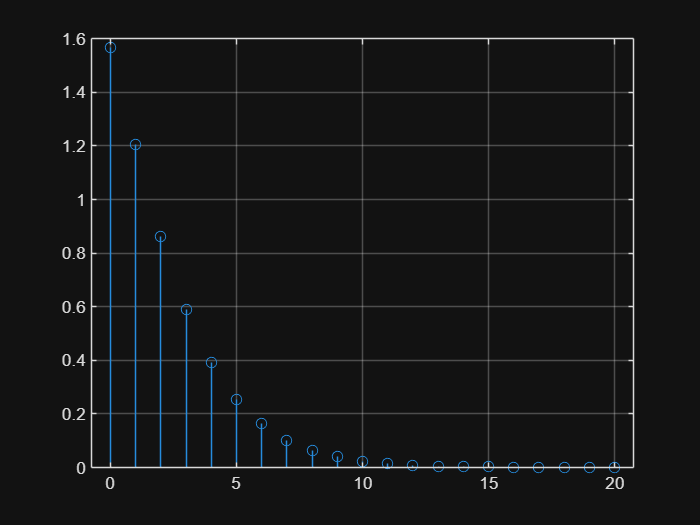

n = 0:20;
a = 0.4*sqrt(2);

x = (a.^n) + a*(n+1).*(a.^n);
stem(n,x);
grid on;

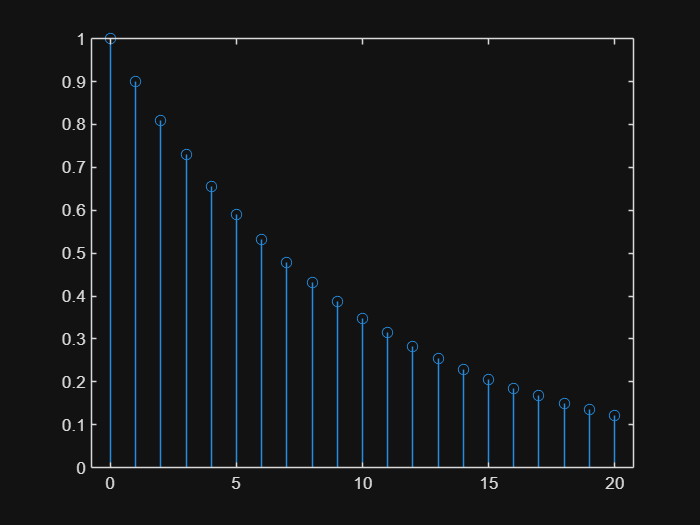

b = [1];
a = [1 -0.9];
n = 0:20;

h = impz(b, a, length(n));
stem(n, h);

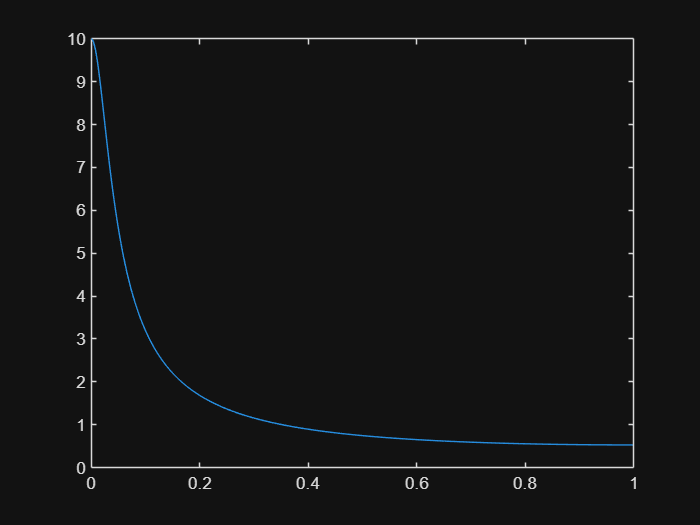


[H, w] = freqz(b, a);
plot(w/pi, abs(H));

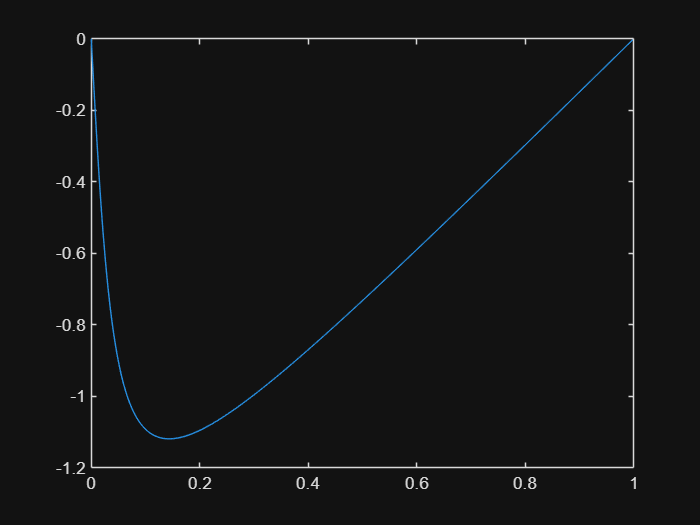

plot(w/pi, angle(H));

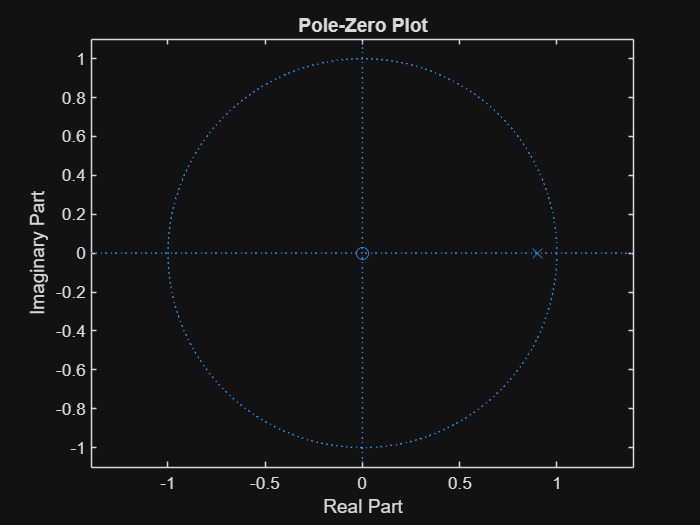


zplane(b, a);

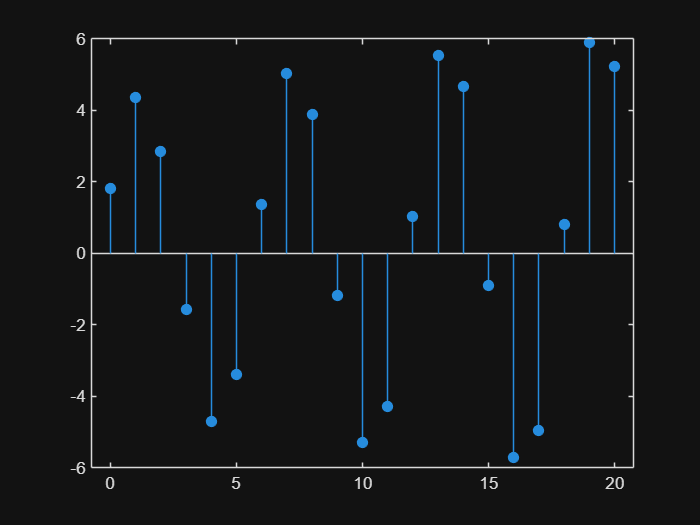

n=0:20;
x=cos((pi*n)/3).*(n>=0);
b=[1/3 1/3 1/3];
a=[1 -0.95 0.9025];

y_init = [-2 -3];   % y(-1), y(-2)
x_init = [1 1];     % x(-1), x(-2)

zi=filtic(b,a,y_init, x_init);
y=filter(b,a,x,zi);
stem(n,y,"filled");